# Valve Design Exercise

The flow rate of cooling fluid through a system is regulated by a valve. The pressure generated by the pump is constant.


$$\Delta P_{pump}=100 \mathrm{bar}$$


The cooling fluid has a specific gravity of 1.1. As a first step, characterize the valve without the system pressure drop. In a second step, determine the best valve trim for a linear relationship between lift and flow for the installed valve.

## Part 1: Valve Characterization

viewSolution(false)

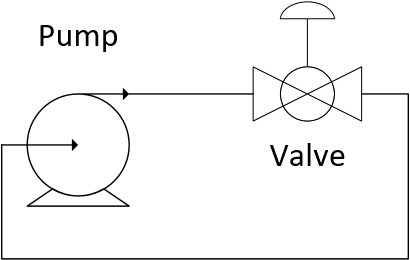

Plot the relationship between flow $q$ and valve lift $l$ for the valve characterized by the design equation.


$$q = C_v f(l) \sqrt{\frac{\Delta P_v}{g_s}}$$


with $C_v=2$ and both a linear lift function $f(l)=l$ and an equal percentage lift function $f(l)=R^{l-1}$ with $R=20$.

*Hint: first, create functions for both linear and equal percentage lift (*$f(l)$*). Then, plot flow(*$q$*) as a function of lift (*$l$).

## Part 2: Installed Valve

viewSolution2(false)

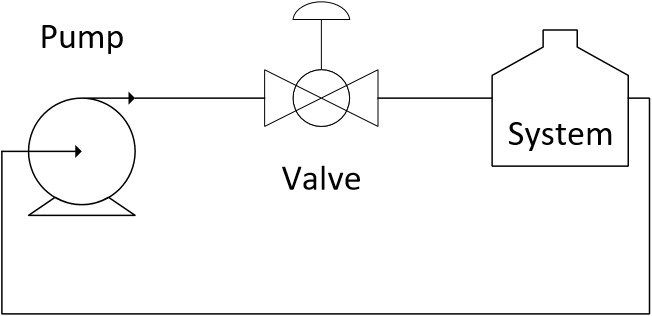

The pressure drop across the system (without the valve) follows the following correlation between pressure drop $\Delta P_{System}$ and flow rate $q$.


$$\Delta P_{system} = 2 q^2$$


Plot the relationship between flow $q$ and valve lift $l$ for the system and valve with $C_v=2$ and either a linear lift function $f(l)=l$ or an equal percentage lift function $f(l)=R^{l-1}$ with $R=20$.

The first step in this solution is to relate the pressure drop across the valve and the system to the pressure generated by the pump.


$$\Delta P_{pump} = \Delta P_v + \Delta P_{system}$$


with


$$\Delta P_{pump} = 100$$



$$\Delta P_v = g_s \left(\frac{q}{C_v f(l)}\right)^2$$



$$\Delta P_{system} = 2 q^2$$


This gives a combined equation in terms of lift $l$ and flow $q$.


$$100 = g_s \left(\frac{q}{C_v f(l)}\right)^2 + 2 q^2$$


Algebraic manipulation is then used to obtain flow as a function of lift $f(l)$ for the valve and system.


$$q(l) = \sqrt{\frac{100\left(C_v f(l)\right)^2}{(g_s + 2 \left(C_v f(l)\right)^2)}}$$


### Solutions

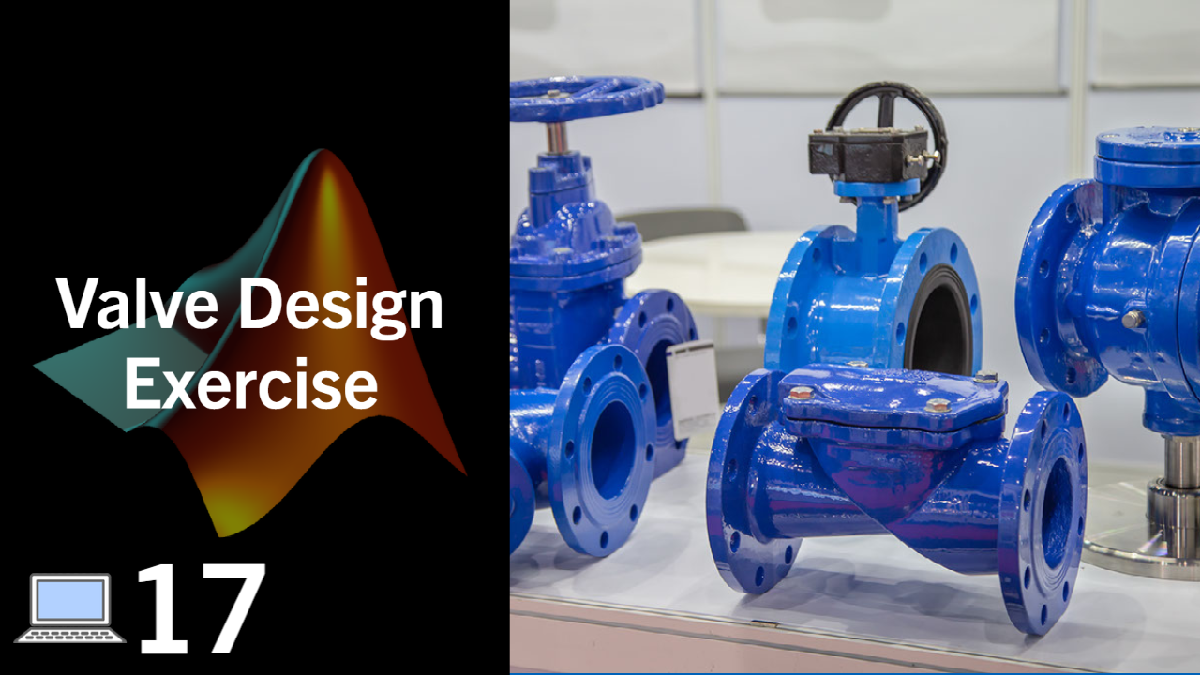

### [View Solution Video](https://youtu.be/aX99Oub2P7o)

function viewSolution(view)
if view
	disp("% lift functions" + newline + ...
	     "f_linear = @(l)l;" + newline + ...
	     "f_equalPercentage = @(l)20.^(l-1);" + newline + ...
	     "" + newline + ...
	     "lift = linspace(0,1,101);  % array for x-axis with possible slopes" + newline + ...
	     "" + newline + ...
	     "% create function for flow which uses lift, the function for lift, valve" + newline + ...
	     "% coefficient, and pressure change" + newline + ...
	     "flow = @(l, f, Cv, dP)Cv*f(l)*sqrt(dP/1.1);" + newline + ...
	     "" + newline + ...
	     "dP = 100;" + newline + ...
	     "Cv = 2;" + newline + ...
	     "flow_linear = flow(lift, f_linear, Cv, dP);" + newline + ...
	     "flow_equalPercentage = flow(lift, f_equalPercentage, Cv, dP);" + newline + ...
	     "" + newline + ...
	     "% Plot" + newline + ...
	     "plot(lift, flow_linear, 'b-', 'DisplayName','Linear Flow')" + newline + ...
	     "hold on" + newline + ...
	     "plot(lift, flow_equalPercentage, 'r--', 'DisplayName','Equal Percentage Flow')" + newline + ...
	     "hold off" + newline + ...
	     "legend('Location','best')" + newline + ...
	     "xlabel('Fractional Lift')" + newline + ...
	 "end")
end
end

function viewSolution2(view)
if view
	disp("% lift functions" + newline + ...
	     "f_linear = @(l)l;" + newline + ...
	     "f_equalPercentage = @(l)20.^(l-1);" + newline + ...
	     "" + newline + ...
	     "lift = linspace(0,1,101);  % array for x-axis with possible slopes" + newline + ...
	     "" + newline + ...
	     "% Differential Pressures" + newline + ...
	     "dP = 100;" + newline + ...
	     "dP_system = @(q)2*q.^2;" + newline + ...
	     "" + newline + ...
	     "% Constants" + newline + ...
	     "Cv = 2;" + newline + ...
	     "g_s = 1.1;" + newline + ...
	     "" + newline + ...
	     "% Flow Equation" + newline + ...
	     "flow = @(l, f) sqrt((Cv.*f(l)).^2*dP ./ (g_s + (Cv.*f(l)).^2 .* Cv));" + newline + ...
	     "" + newline + ...
	     "flow_linear = flow(lift, f_linear);" + newline + ...
	     "flow_equalPercentage = flow(lift, f_equalPercentage);" + newline + ...
	     "" + newline + ...
	     "" + newline + ...
	     "% Plot" + newline + ...
	     "figure(2)" + newline + ...
	     "subplot(3,1,1)" + newline + ...
	     "plot(lift, flow_linear, 'b-', 'DisplayName','Linear Flow')" + newline + ...
	     "hold on" + newline + ...
	     "plot(lift, flow_equalPercentage, 'r--', 'DisplayName','Equal Percentage Flow')" + newline + ...
	     "hold on" + newline + ...
	     "plot([0,1], [0,6.5], 'k-', 'DisplayName','Desired Profile')" + newline + ...
	     "hold off" + newline + ...
	     "legend('Location','best')" + newline + ...
	     "ylabel('Flow')" + newline + ...
	     "subplot(3,1,2)" + newline + ...
	     "plot(lift, dP - dP_system(flow_linear), 'b-', 'DisplayName','Linear Valve')" + newline + ...
	     "hold on" + newline + ...
	     "plot(lift, dP_system(flow_linear), 'r--', 'DisplayName','Process Equipment')" + newline + ...
	     "hold off" + newline + ...
	     "ylabel('$\Delta P$', 'Interpreter','latex')" + newline + ...
	     "legend('Location','best')" + newline + ...
	     "subplot(3,1,3)" + newline + ...
	     "plot(lift, dP - dP_system(flow_equalPercentage), 'b-', 'DisplayName','Linear Valve')" + newline + ...
	     "hold on" + newline + ...
	     "plot(lift, dP_system(flow_equalPercentage), 'r--', 'DisplayName','Process Equipment')" + newline + ...
	     "hold off" + newline + ...
	     "legend('Location','best')" + newline + ...
	     "ylabel('$\Delta P$', 'Interpreter','latex')" + newline + ...
	 "end")
end
end
